# **Simulación 2 Robots**

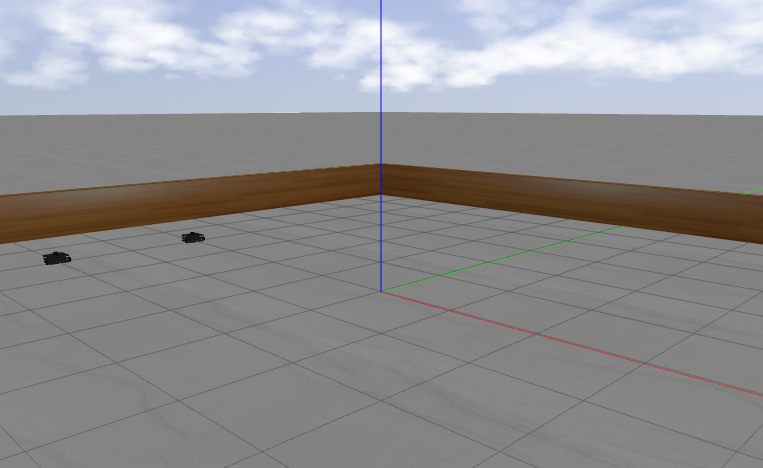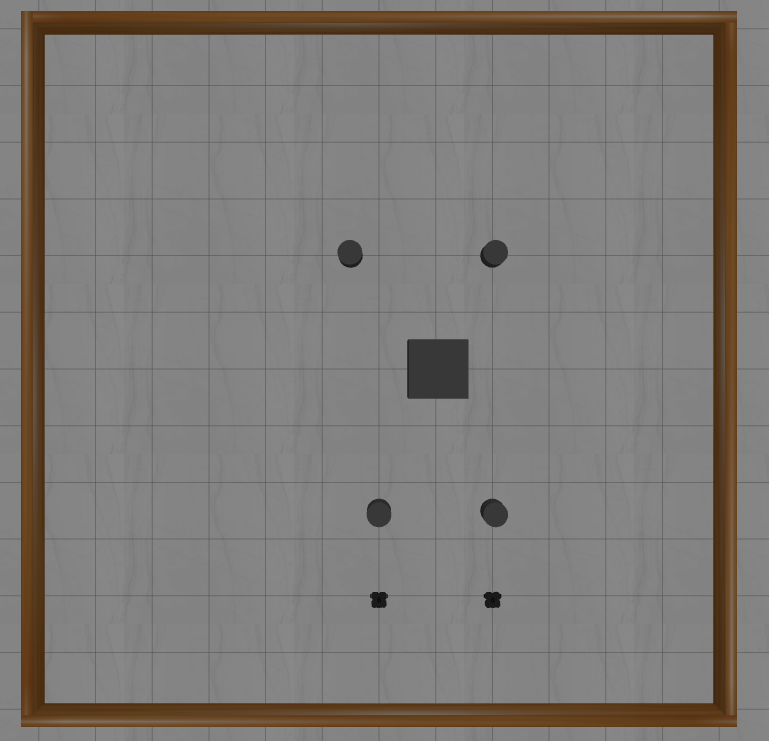

## Simulación 

- Mapa con 2 agentes

% setup enviroment 
clear, clc, close all

Tiempo de Simulación:

% Variables de inicialización
t_sim=30;

Ajuste controlador VFH+ y Pure Pursuit:

%%Inicialización controlador PurePursuit
PP=controllerPurePursuit;
% PP.Waypoints=Way;
PP.MaxAngularVelocity=1.82; %rad/s 
PP.DesiredLinearVelocity=0.2;% m/s
PP.LookaheadDistance=0.5; %m 
%%Inicialización Algoritmo VFH
VFH = controllerVFH;
VFH.UseLidarScan=true;
VFH.NumAngularSectors=360;
VFH.DistanceLimits=[0.3,3.5];
VFH.RobotRadius=0.22;
VFH.SafetyDistance=0.35;
VFH.MinTurningRadius=0.4;
VFH.HistogramThresholds=[5,15];

Seleccione la prueba a realizar:

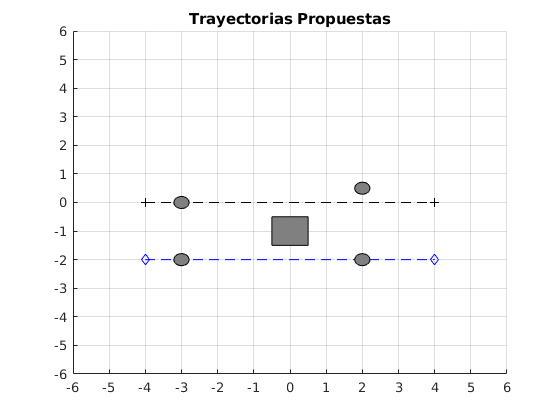

form=2;
if form==1
    Way1=[-4 -2; -2 0];
    Way2=[-4  0; -2 -2];
elseif form==2
    Way1=[-4 -2; 4 -2];
    Way2=[-4  0; 4 0];   
end




 

close
figure()
hold on

plot(Way1(:,1),Way1(:,2),'b--d');
plot(Way2(:,1),Way2(:,2),'k--+');

xticks(-6:6)
yticks(-6:6)
select="Con_Obstaculos";
%% Inserción Obstaculo
if select=="Con_Obstaculos"
r=0.21;
pos = [-3-r 0-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [-3-r -2-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [2-r -2-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [2-r 0.5-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
rectangle('Position',[-0.5 -1.5 1 1],'FaceColor',[.5 .5 .5])
end
%%fin inserción
grid on
xlim([-6,6])
ylim([-6,6])
title("Trayectorias Propuestas")

% legend("Way1","Way2","Location","bestoutside")




# Ejecutar 

# Two_Robots.slx

Ejecutar al finalizar la ejecución del .slx

%Data robot 1
t1=actuators1.time;
U1=actuators1.signals.values(:,1);
W1=actuators1.signals.values(:,2);
Lidar1.angles=angles1.signals.values;
Lidar1.ranges=ranges1.signals.values;
X1=pose1.signals.values(:,1);
Y1=pose1.signals.values(:,2);
YAW1=pose1.signals.values(:,3);
TD1=targetDir1.signals.values(1,:);
[it_max1,~]=size(Lidar1.ranges);
%Data robot 2
t2=actuators2.time;
U2=actuators2.signals.values(:,1);
W2=actuators2.signals.values(:,2);
Lidar2.angles=angles2.signals.values;
Lidar2.ranges=ranges2.signals.values;
X2=pose2.signals.values(:,1);
Y2=pose2.signals.values(:,2);
YAW2=pose2.signals.values(:,3);
TD2=targetDir2.signals.values(1,:);
[it_max2,~]=size(Lidar2.ranges);
 

## Gráficas:

cte=1;

### Posiciones:

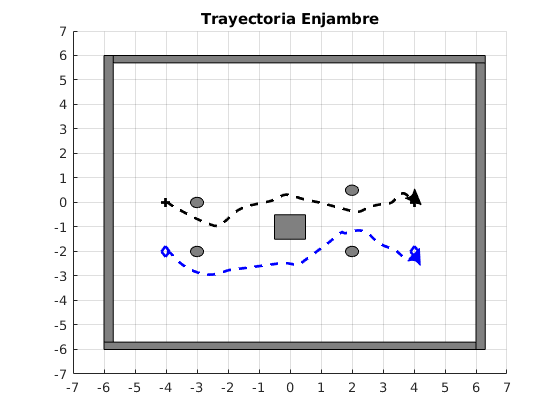

 
close
figure();
hold on
lim=6;
plot(Way1(:,1),Way1(:,2),'bd','LineWidth',2);
plot(Way2(:,1),Way2(:,2),'k+','LineWidth',2);
r=0.21;
%% Inserción Obstaculo
if select=="Con_Obstaculos"
pos = [-3-r 0-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [-3-r -2-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [2-r -2-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
pos = [2-r 0.5-r 2*r 2*r]; 
rectangle('Position',pos,'Curvature',[1 1],'FaceColor',[.5 .5 .5])
rectangle('Position',[-0.5 -1.5 1 1],'FaceColor',[.5 .5 .5])
end
%%fin inserción


rectangle('Position',[-0.5 -1.5 1 1],'FaceColor',[.5 .5 .5])

if form==1
   lim=lim;
elseif form==2
    lim=lim+1;
    rectangle('Position',[6 -6 0.3 12],'FaceColor',[.5 .5 .5])
    rectangle('Position',[-6 -6 0.3 12],'FaceColor',[.5 .5 .5])
    rectangle('Position',[-6 -6 12 0.3],'FaceColor',[.5 .5 .5])
    rectangle('Position',[-5.7 5.7 12 0.3],'FaceColor',[.5 .5 .5])    
end

    xticks(-lim:lim)
    yticks(-lim:lim)
    xlim([-lim,lim])
    ylim([-lim,lim])
grid on
title("Trayectoria Enjambre")
%Inicialización robots

ar1=arrow_draw(X1(1),Y1(1),YAW1(1),lim,'b');
% pa1=rectangle('Position',[X1(1)-r Y1(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'b','FaceColor','b');
plot(X1(1),Y1(1),'b')
ar2=arrow_draw(X2(1),Y2(1),YAW2(1),lim,'k');
% pa2=rectangle('Position',[X2(1)-r Y2(1)-r 2*r 2*r],'Curvature',[1 1],"EdgeColor",'k','FaceColor','k');
plot(X2(1),Y2(1),'k')

% legend("AutoUpdate","off")
% legend("Way1","Way2"...
%     ,"Trayectoria1","Trayectoria2"...
%     ,"Location","bestoutside")
for i=1:(min([length(X1), length(X2)]))/cte
%     plot(X(i),Y(i),'b>')
%Robot1
%     pos = [X1(i)-r Y1(i)-r 2*r 2*r]; 
    delete(ar1);
    plot(X1(1:i),Y1(1:i),'--b','LineWidth',2)
%     pa1=rectangle('Position',pos,'Curvature',[1 1],"EdgeColor",'b','FaceColor','b');
    
%Robot2    
%     pos = [X2(i)-r Y2(i)-r 2*r 2*r]; 
    delete(ar2);
    plot(X2(1:i),Y2(1:i),'--k','LineWidth',2)
%     pa2=rectangle('Position',pos,'Curvature',[1 1],"EdgeColor",'k','FaceColor','k');   
    %     legend("Waypoints","Trayectoria Real")
    ar1=arrow_draw(X1(i),Y1(i),YAW1(i),lim,'b');
    ar2=arrow_draw(X2(i),Y2(i),YAW2(i),lim,'k');
    pause(0.1)
end 
hold off

### Velocidades:

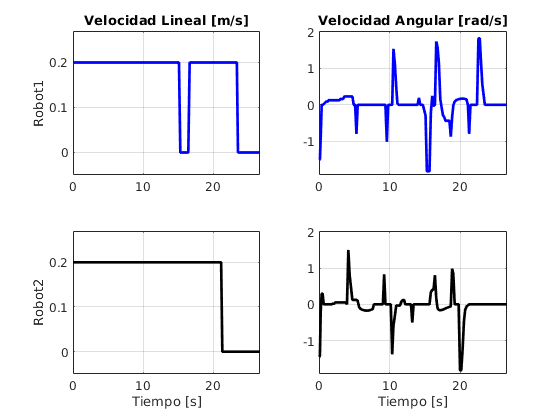

 
figure()
hold on
maxv=0.22;
maxw=1.82;
l1=ones(1,length(t1));
l2=ones(1,length(t2));
%R1
subplot(2,2,1)
plot(t1,U1,'b','LineWidth',2);
hold on
% plot(t1,maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t1,-maxv*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Lineal [m/s]")
ylabel("Robot1")
ylim([min(U1)-0.05,maxv+0.05])
xlim([0 t1(end)])
grid on
subplot(2,2,2)
plot(t1,W1,'b','LineWidth',2);
hold on
% plot(t1,maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t1,-maxw*l1,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
title("Velocidad Angular [rad/s]")
ylim([min(W1)-0.1,maxw+0.2])
xlim([0 t1(end)])
grid on


%R2
subplot(2,2,3)
plot(t2,U2,'k','LineWidth',2);
hold on
% plot(t2,maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2,'LineWidth',2);
% plot(t2,-maxv*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2,'LineWidth',2);
hold off
ylim([min(U2)-0.05,maxv+0.05])
xlim([0 t2(end)])
ylabel("Robot2")
xlabel('Tiempo [s]')
grid on
subplot(2,2,4)
plot(t2,W2,'k','LineWidth',2);
hold on
% plot(t2,maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
% plot(t2,-maxw*l2,"Color",[0.6350 0.0780 0.1840],"LineStyle","--",'LineWidth',2);
hold off
ylim([min(W2)-0.1,maxw+0.2])
xlim([0 t2(end)])
xlabel('Tiempo [s]')
grid on

### LIDAR

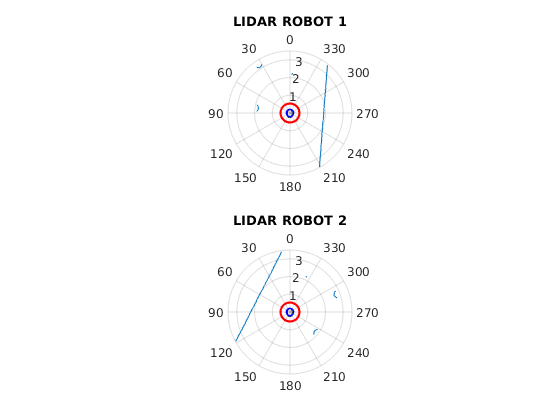

 
% rob=0.5*ones(1,it_max);
RR=VFH.RobotRadius*ones(1,360);
SD=VFH.SafetyDistance+RR;
theta=1:360;
figure
%Robot1
for i=1:min([it_max1,it_max2])
  %Robot 1  
  subplot(2,1,1)
  polarplot(Lidar1.angles(i,:),Lidar1.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 1")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  hold off
  %Robot 2  
  subplot(2,1,2)
  polarplot(Lidar2.angles(i,:),Lidar2.ranges(i,:))
  ax = gca;
  ax.ThetaZeroLocation = 'top';
  rlim([0 3.5])
  title("LIDAR ROBOT 2")
  hold on
  polarplot(theta,RR,'b')
  polarplot(theta,SD,'r')
  
  hold off
  pause(0.1) 
end

### VFH (Vector Field Histogram):

step=2;

`VFH1:`

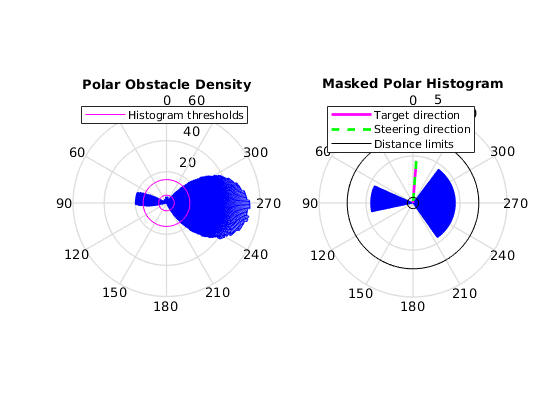

 
for i=1:step:it_max1
%     figure
    scan=lidarScan(Lidar1.ranges(i,:),Lidar1.angles(i,:));
    targetDir =TD1(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end

`VFH2:`

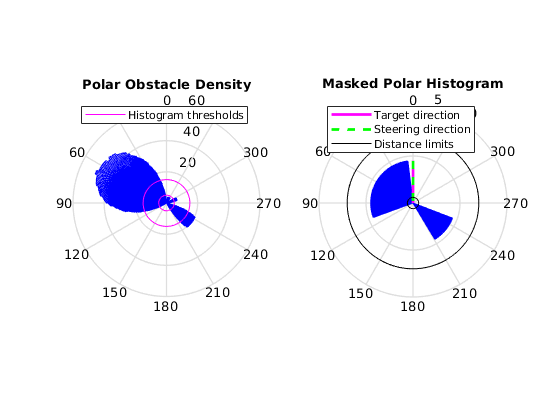

 
for i=1:step:it_max2
%     figure
    scan=lidarScan(Lidar2.ranges(i,:),Lidar2.angles(i,:));
    targetDir =TD2(i);
    VFH(scan,targetDir);
    show(VFH);
    pause(0.1) 
end